HA_flow = readtable('Hepatic Artery Flow_MovAvg_11pt.csv');
HA_pressure = readtable('Hepatic Artery Pressure_MovAvg_11pt.csv');
PV_flow = readtable('Portal Vein Flow_MovAvg_11pt.csv');
PV_pressure = readtable('Portal Vein Pressure_MovAvg_11pt.csv');
PV_labs = readtable('PortalVeinLabs.csv');

HA_labs = readtable('HepaticArteryLabs.csv');


HA_pressure_time = table2array(HA_pressure(:,"Var1"));
% ex = HA_pressure_time_raw(1,:);
% HA_pressure_time = HA_pressure_time_raw - ex;

HA_labs_time_raw = table2array(HA_labs(:,1));
HA_labs_time = HA_labs_time_raw - ex;

HA_labs_pressures = table2array(HA_labs(:,20))

HA_labs_pressures =        NaN
       NaN
       NaN
       NaN
   53.6010
   55.0800
   55.0800
       NaN
   50.3880
   50.3880



pressure_mask = [];
for i = 1:length(HA_labs_pressures)
    temp = ~isnan((HA_labs_pressures(i)));
    pressure_mask = [pressure_mask temp];
end

%pressure_mask = logical(pressure_mask ==1)




HA_labs_time = HA_labs_time(find(pressure_mask ==1));
HA_labs_pressures = HA_labs_pressures(find(pressure_mask ==1));

% HA_labs_pressure_final = [];
% for i = 1:length(HA_labs_pressures)
%     temp = HA_labs_pressures(i);
%     HA_labs_pressure_final = [HA_labs_pressure_final temp];
% end



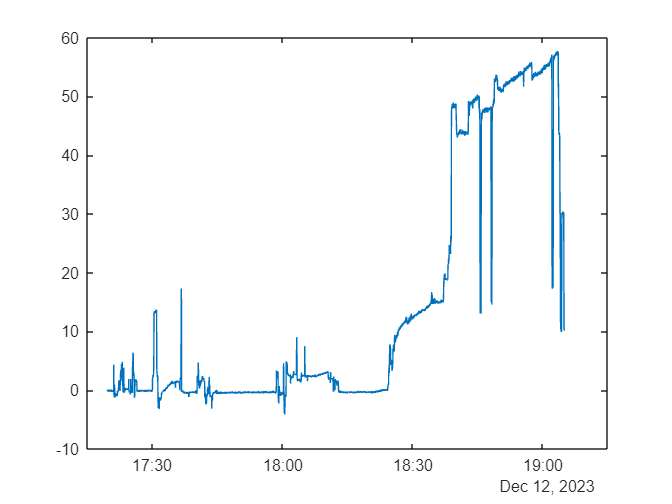


PV_pressure_time_raw = table2array(PV_pressure(:,"Var1"));
ex = PV_pressure_time_raw(1,:);
PV_pressure_time = PV_pressure_time_raw - ex;

PV_labs_time_raw = table2array(PV_labs(:,1));
PV_labs_time = PV_labs_time_raw - ex;

PV_labs_pressures = (table2array(PV_labs(:,20)));

pressure_mask = [];
for i = 1:length(PV_labs_pressures)
    temp = ~isnan(str2double((PV_labs_pressures(i))));
    pressure_mask = [pressure_mask temp];
end

pressure_mask =logical(pressure_mask);

PV_labs_time = PV_labs_time(pressure_mask);
PV_labs_pressures = PV_labs_pressures(pressure_mask);

PV_labs_pressure_final = [];
for i = 1:length(PV_labs_pressures)
    temp = str2num(PV_labs_pressures(i));
    PV_labs_pressure_final = [PV_labs_pressure_final temp];
end

HApressure = table2array(HA_pressure(:,2));
plot(HA_pressure_time, HApressure)
hold on

PVpressure = table2array(PV_pressure(:,2));
plot(PV_pressure_time, PVpressure)

Error using matlab.graphics.internal.configureAxes
Values plotted against x-axis must be datetime values. To create datetime values, use the datetime function.

Error in matlab.graphics.internal.configureAxes

legend('HA','PV')
title('Pressure (mmHg)')
hold off

HA_pressure_NaN = find(table2array(HA_pressure(:,2))<0);

HApressure(HA_pressure_NaN) = [];
HA_pressure_time(HA_pressure_NaN) = [];

plot(HA_pressure_time, HApressure)
title("HA Pressure (mmHg) RAW")
hold off

PV_pressure_NaN = find(table2array(PV_pressure(:,2))<0);

PVpressure(PV_pressure_NaN) = [];
PV_pressure_time(PV_pressure_NaN) = [];

plot(PV_pressure_time, PVpressure)
title("PV Pressure (mmHg) RAW")
hold off

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
pointsInAvg = 5000;
coeffMovingAvg = ones(1, pointsInAvg)/pointsInAvg;

HA_pressure_time = hours([HA_pressure_time; HA_labs_time]);
avgHAPressure = filter(coeffMovingAvg, 1, HApressure);
avgHAPressure = [avgHAPressure; HA_labs_pressure_final'];
plot(HA_pressure_time,avgHAPressure)
title("Filtered HA Pressure")
ylabel("mmHg")
xlabel("Hours")

PV_pressure_time = hours([PV_pressure_time; PV_labs_time]);
avgPVPressure = filter(coeffMovingAvg, 1, PVpressure);
avgPVPressure = [avgPVPressure; PV_labs_pressure_final'];
plot(PV_pressure_time,avgPVPressure)
title("Filtered PV Pressure")
ylabel("mmHg")
xlabel("Hours")


plot(PV_pressure_time,avgPVPressure, "LineWidth", 2)
hold on
plot(HA_pressure_time,avgHAPressure, "LineWidth", 2)
title("Pressure")
legend("HA Pressure", "PV Pressure")
ylabel("mmHg")
xlabel("Hours")
hold off

PV_pressure_data = [PV_pressure_time, avgPVPressure];
HA_pressure_data = [HA_pressure_time, avgHAPressure];

csvwrite("PV Pressures Complete.csv", PV_pressure_data);
csvwrite("HA Pressure Complete.csv", HA_pressure_data);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%